# Parameter Analysis

uses the **minCOT.m** function to analyze parameters of interest:

- **forward speed (xdot_target)**

- **leg inertia (I)**

- **spring constant (k)**

- **damping constant (c)**

clearvars; clc; close all;

### Validation: Double check the solution is close to the single opt solutions

addpath('functions/singleOpt');
[m, g, k, c, la0, laRange, target_speed, target_freq, I, t_sim, l_uN] = physConstants('r');
rmpath('functions/singleOpt');

addpath('functions/multiOpt');
addpath('functions/sharedFuncs');
addpath('warmStartTemplates');
addpath('data');
[COT, stanceCost, flightCost, tstance, tflight, w_star] = minCOT('r', target_speed, target_freq, k, c, I, 0);

Mode: r | Speed: 0.60 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template


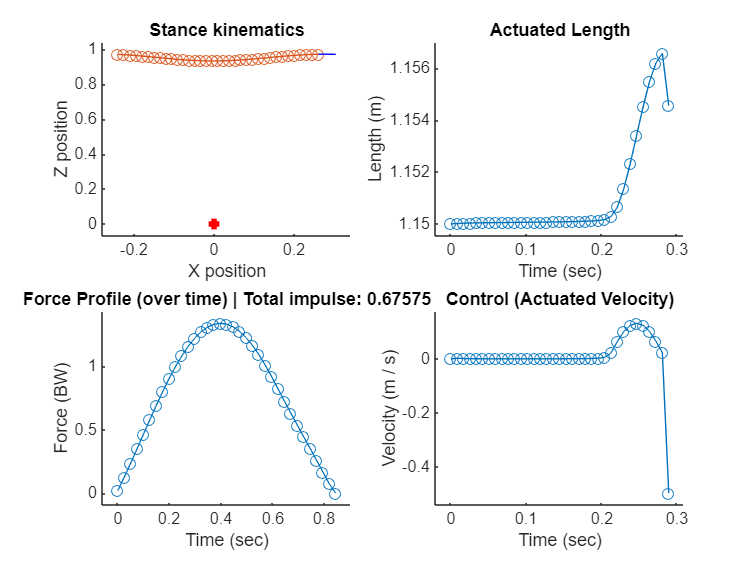

rmpath('functions/multiOpt');
rmpath('functions/sharedFuncs');
rmpath('warmStartTemplates');
rmpath('data');

close all;
addpath('functions/singleOpt');
addpath('functions/sharedFuncs');
plotTraj(w_star, '', 'h');

rmpath('functions/sharedFuncs');
rmpath('functions/singleOpt');

### **Analysis 1: Forward Speed vs. Leg Inertia**

% add necessary paths
addpath('functions/multiOpt');
addpath('functions/sharedFuncs');
addpath('warmStartTemplates');
addpath('data');

% some constants
addpath('functions/singleOpt');
[~, ~, k_run, c_run, ~, ~, ~, ~, I, ~, ~] = physConstants('r');
[~, ~, k_hop, c_hop, ~, ~, target_speed, target_freq, ~, t_sim, l_uN] = physConstants('h');
rmpath('functions/singleOpt');

speeds = linspace(target_speed*0.5, target_speed*2, 7);
inertias = linspace(I*0.5, I*2, 7);

#### Run optimization sweep

Several things added:

- isNotExpected function to rerun in case of weird output (happens but not sure why)

- Creating a mesh by creating rows then appending rows together

- first block is nonparallelized code (written by me)

- second block is parallelized code (written by gemini, requiring the parallel computing toolbox)

% NON PARALLELIZED VERSION
num_speeds = numel(speeds);
num_inertias = numel(inertias);

running_COTs = zeros(num_inertias, num_speeds);
hopping_COTs = zeros(num_inertias, num_speeds);
next_guess = 0;

for I_idx=1:num_inertias
    I = inertias(I_idx);
    runCOT_tmpRow = zeros(1, num_speeds);
    hopCOT_tmpRow = zeros(1, num_speeds);
    for s_idx=1:num_speeds
        speed = speeds(s_idx);

        % to recompute if weird value appears
        [runCOT, ~, ~, ~, ~] =...
            robustMinCOT('r', speed, k, c, I, 0, runCOT_tmpRow);
        runCOT_tmpRow(s_idx) = runCOT;

        [hopCOT, ~, ~, ~, ~] =...
            robustMinCOT('h', speed, k, c, I, 0, hopCOT_tmpRow);
        hopCOT_tmpRow(s_idx) = hopCOT;

    end
    running_COTs(I_idx, :) = runCOT_tmpRow;
    hopping_COTs(I_idx, :) = hopCOT_tmpRow;
end

% PARALLELIZED VERSION (GENERATED WITH GEMINI FROM THE CODE ABOVE)
num_inertias = length(inertias);
num_speeds   = length(speeds);

% Preallocate output matrices
running_COTs = zeros(num_inertias, num_speeds);
hopping_COTs = zeros(num_inertias, num_speeds);

cluster = parcluster('Processes');
cluster.NumWorkers = num_inertias;
saveProfile(cluster);
parpool(num_inertias);
parfor I_idx = 1:num_inertias
    next_guess_run = 0;
    next_guess_hop = 0;

    I = inertias(I_idx);
    
    % Preallocate local row vectors for this worker's iteration
    runCOT_tmpRow = zeros(1, num_speeds);
    hopCOT_tmpRow = zeros(1, num_speeds);
    
    for s_idx = 1:num_speeds
        speed = speeds(s_idx);
        
        % --- Running COT ---
        % Pass the preallocated slice up to the current index
        [runCOT, ~, ~, ~, ~, next_guess_run] = ...
            robustMinCOT('r', speed, target_freq, k_run, c_run, I, next_guess_run);
        runCOT_tmpRow(s_idx) = runCOT;
        
        % --- Hopping COT ---
        % Pass the preallocated slice up to the current index
        [hopCOT, ~, ~, ~, ~, next_guess_hop] = ...
            robustMinCOT('h', speed, target_freq, k_hop, c_hop, I, next_guess_hop);
        hopCOT_tmpRow(s_idx) = hopCOT;
    end
    
    % Assign the clean rows to the global matrices
    running_COTs(I_idx, :) = runCOT_tmpRow;
    hopping_COTs(I_idx, :) = hopCOT_tmpRow;
end

**The data generated from the code above is stored in dataspaces/speedInertiaSweep.mat*

figure;
hold on;
surf(speeds * (l_uN / t_uN), inertias, running_COTs, 'FaceColor', 'red');
surf(speeds * (l_uN / t_uN), inertias, hopping_COTs,'FaceColor', 'blue');
xlabel("Speed");
ylabel("Leg Inertias");
zlabel("Cost");
title("Cost as a function of speed and leg inertias. " + ...
    "k = " + k + " | c = " + c  + " | m = " + m);
legend("running", "hopping");
hold off;

#### Results:

The plot shows that running is more favorable at higher leg inertias. However, the plot also shows that hopping is more favorable at higher speeds. Thus, the next step is to examine the individual portions of cost and step period to examine which elements of the gait are driving this trend.

#### Analysis 1.2: Cost of phases and time periods across various speeds

clc; clear; close all;

% m = 1;

addpath('functions/singleOpt');
[~, ~, k_run, c_run, ~, ~, ~, target_freq_r, I, ~, ~] = physConstants('r');
[~, ~, k_hop, c_hop, ~, ~, target_speed, target_freq_h, ~, t_sim, l_uN] = physConstants('h');
rmpath('functions/singleOpt');

speeds = linspace(target_speed*(1/3), target_speed*2.5, 10);

% BASED ON PARALLELIZAITON CODE ABOVE

num_speeds = length(speeds);

% 1. Preallocate matrices for parallel efficiency and sliced variable compliance
runCOTs = zeros(1, num_speeds);
run_stance_costs = zeros(1, num_speeds);
run_flight_costs = zeros(1, num_speeds);
run_stance_periods = zeros(1, num_speeds);
run_flight_periods = zeros(1, num_speeds);

hopCOTs = zeros(1, num_speeds);
hop_stance_costs = zeros(1, num_speeds);
hop_flight_costs = zeros(1, num_speeds);
hop_stance_periods = zeros(1, num_speeds);
hop_flight_periods = zeros(1, num_speeds);

% cluster = parcluster('Processes');
% cluster.NumWorkers = num_speeds;
% saveProfile(cluster);
% parpool(num_speeds);
parfor s_idx = 1:num_speeds
    speed = speeds(s_idx);

    next_guess_run = 0;
    next_guess_hop = 0;
    
    % --- Running COT ---
    [runCOT, run_stance_cost, run_flight_cost, run_tstance, run_tflight, next_guess_run] = ...
        robustMinCOT('r', speed, target_freq_r, k_run, c_run, I, next_guess_run);
    runCOTs(s_idx) = runCOT;
    run_stance_costs(s_idx) = run_stance_cost;
    run_flight_costs(s_idx) = run_flight_cost;
    run_stance_periods(s_idx) = run_tstance;
    run_flight_periods(s_idx) = run_tflight;
    
    % --- Hopping COT ---
    % Pass the preallocated slice up to the current index
    [hopCOT, hop_stance_cost, hop_flight_cost, hop_tstance, hop_tflight, next_guess_hop] = ...
        robustMinCOT('h', speed, target_freq_h, k_hop, c_hop, I, next_guess_hop);  % minCOT doubles I already
    hopCOTs(s_idx) = hopCOT;
    hop_stance_costs(s_idx) = hop_stance_cost;
    hop_flight_costs(s_idx) = hop_flight_cost;
    hop_stance_periods(s_idx) = hop_tstance;
    hop_flight_periods(s_idx) = hop_tflight;
end

Mode: r | Speed: 2.02 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 1.59 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 1.37 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 2.23 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 0.73 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 1.16 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 0.51 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 1.80 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 0.94 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: r | Speed: 0.30 | k, c, I: 2.750000e+01 0.15 0.04630
using warm start template
Mode: h | Speed: 1.80 | k, c, I: 20 0.10 0.04630
using warm start template
Mode: h | Speed: 1.59 | k, c, I: 20 0.10 0.04630
using warm start template


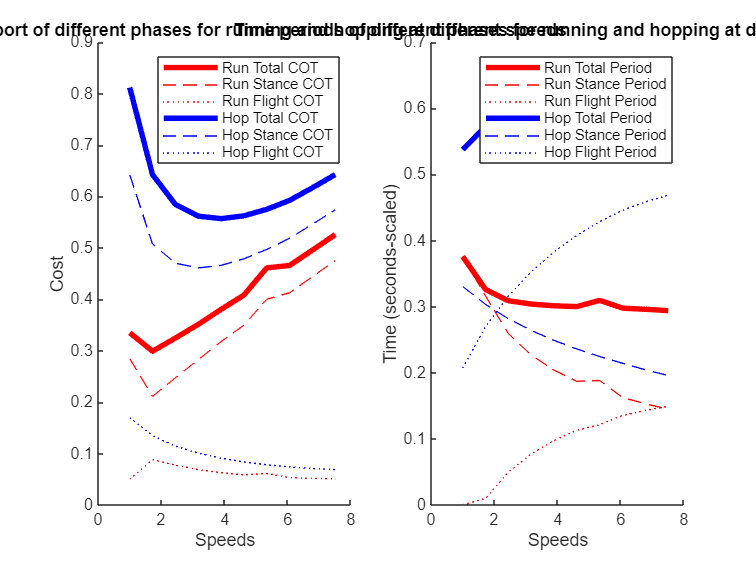

close all;
plt_speeds = speeds * (l_uN / t_sim);

figure;
subplot(1, 2, 1);
hold on;
plot(plt_speeds, runCOTs, "r-", "LineWidth", 3);
plot(plt_speeds, run_stance_costs, "r--");
plot(plt_speeds, run_flight_costs, "r:");

plot(plt_speeds, hopCOTs, "b-", "LineWidth", 3);
plot(plt_speeds, hop_stance_costs, "b--");
plot(plt_speeds, hop_flight_costs, "b:");

xlabel Speeds;
ylabel Cost;
legend("Run Total COT", "Run Stance COT", "Run Flight COT",...
       "Hop Total COT", "Hop Stance COT", "Hop Flight COT");
title("Cost of transport of different phases for running and hopping at different speeds");
hold off;

subplot(1, 2, 2);
hold on;
% scaled
plot(plt_speeds, (run_stance_periods + run_flight_periods) * t_sim, "r-", "LineWidth", 3);
plot(plt_speeds, run_stance_periods * t_sim, "r--");
plot(plt_speeds, run_flight_periods * t_sim, "r:");

plot(plt_speeds, (hop_stance_periods + hop_flight_periods) * t_sim, "b-", "LineWidth", 3);
plot(plt_speeds, hop_stance_periods * t_sim, "b--");
plot(plt_speeds, hop_flight_periods * t_sim, "b:");

xlabel Speeds;
ylabel("Time (seconds-scaled)");
legend("Run Total Period", "Run Stance Period", "Run Flight Period",...
       "Hop Total Period", "Hop Stance Period", "Hop Flight Period");
title("Time periods of different phases for running and hopping at different speeds");

hold off;

### Analysis 2: Forward Speed vs. Spring Constant

clc; clear; close all;

% some constants
clc; clear; close all;

m = 1;
k = 15;
c = 0.4;
I = 4.63e-2;

speeds = 1:0.5:7;
ks = 10:2.5:20;

% some constants
addpath('functions/singleOpt');
[~, ~, k_run, c_run, ~, ~, ~, ~, I, ~, ~] = physConstants('r');
[~, ~, k_hop, c_hop, ~, ~, target_speed, target_freq, ~, t_sim, l_uN] = physConstants('h');
rmpath('functions/singleOpt');

speeds = linspace(target_speed*0.5, target_speed*2, 7);
k_runs = linspace(k_run*0.5, k_run*2);
k_hops = linspace(k_hop*0.5, k_hop*2);

#### Run optimization sweep:

- The exact same code block as above but with spring constant varying instead of leg inertia

% BASED ON PARALLELIZE CODE IN (1)

num_ks = length(k_runs);
num_speeds   = length(speeds);

% Preallocate output matrices
running_COTs = zeros(num_ks, num_speeds);
hopping_COTs = zeros(num_ks, num_speeds);

cluster = parcluster('Processes');
cluster.NumWorkers = num_ks;
saveProfile(cluster);
parpool(num_ks);
parfor k_idx = 1:num_ks
    next_guess_run = 0;
    next_guess_hop = 0;

    k_run = k_runs(k_idx);
    k_hop = k_hops(k_idx);
    
    % Preallocate local row vectors for this worker's iteration
    runCOT_tmpRow = zeros(1, num_speeds);
    hopCOT_tmpRow = zeros(1, num_speeds);
    
    for s_idx = 1:num_speeds
        speed = speeds(s_idx);
        
        % --- Running COT ---
        % Pass the preallocated slice up to the current index
        [runCOT, ~, ~, ~, ~, next_guess_run] = ...
            robustMinCOT('r', speed, target_freq, k_run, c, I, next_guess_run);
        runCOT_tmpRow(s_idx) = runCOT;
        
        % --- Hopping COT ---
        % Pass the preallocated slice up to the current index
        [hopCOT, ~, ~, ~, ~, next_guess_hop] = ...
            robustMinCOT('h', speed, target_freq, k_hop, c, I, next_guess_hop);
        hopCOT_tmpRow(s_idx) = hopCOT;
    end
    
    % Assign the clean rows to the global matrices
    running_COTs(k_idx, :) = runCOT_tmpRow;
    hopping_COTs(k_idx, :) = hopCOT_tmpRow;
end

figure;

hold on;
surf(speeds, ks, running_COTs, 'FaceColor', 'red');
surf(speeds, ks, hopping_COTs,'FaceColor', 'blue');
xlabel("Speed");
ylabel("Spring Constant (k)");
zlabel("Cost");
title("Cost as a function of speed and spring constants. " + ...
    "I = " + I + " | c = " + c  + " | m = " + m);
legend("running", "hopping");
hold off;

rmpath('functions/multiOpt');
rmpath('functions/sharedFuncs');
rmpath('warmStartTemplates');
rmpath('data');